# SISTEMAS DE CONTROL II

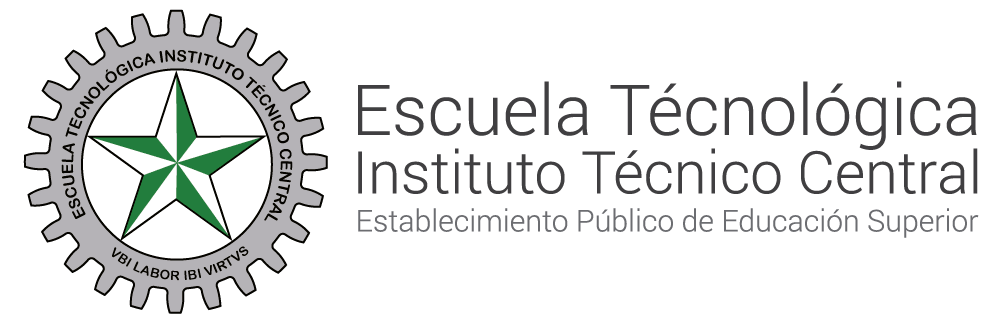

# Lugar Geometrico de las Raices (sistemas discretisados)

**Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c**

**Coautor: JIMMY DE JESUS REYES MANCERA**

### **LUGAR GEOMETRICO DE LAS RAICES EN EL DOMINIO DE Z**

El lugar geométrico de las raíces en el dominio z es una herramienta gráfica que muestra cómo varían las raíces de la función de transferencia de un sistema discreto en el plano z cuando se modifica un parámetro del sistema, generalmente la ganancia K. Este análisis es fundamental para el diseño y ajuste de controladores, ya que permite estudiar la estabilidad y la dinámica del sistema. Las raíces representan los polos del sistema en el plano z, y su ubicación determina características como la respuesta transitoria, la estabilidad y la velocidad de asentamiento.

Para explicar como se hace para hallar los rangos de la ganancia o K se hacen varios procedimientos para entender en que momento puede ser estable el sistema  y como puede ser las respuestas del sistema en funcion del tiempo

### Tener en cuenta antes de todo

Para empezar tenemos que entender que se puede usar el LUGAR GEOMETRICO DE LAS RAICES (LGR) de manera sencilla unicamente teniendo esto en terminos de Z y entendiendo que hay que tener en cuenta la ecuacion o polinomio. $\textrm{GH}\left(z\right)$

Donde $\textrm{GH}\left(z\right)$ es $K\frac{N\left(z\right)}{D\left(z\right)}$ como hemos venido hablando K es la ganancia que puede hacer o inestable o estable el sistema.

Para poder empezar necesitamos sumarle una unidad a todo el polinomio o ecuacion que tenemos del sistema por lo que seria así. $1+\textrm{GH}\left(z\right)=0$

Para ser un poco mas claro. 


$$1+K\frac{\left(z+z_1 \right)\left(z+z_2 \right)\ldotp \ldotp \ldotp \left(z+z_n \right)}{\left(z+p_{1\;} \right)\left(z+p_2 \right)\ldotp \ldotp \ldotp \left(z+p_m \right)}=0$$


### Paso 1 - Ecuacion caracteristica

Para entender como funciona todo esto tendremos la siguiente definicion de sistema:


$$K\frac{\left(0\ldotp 3679z+0\ldotp 2642\right)}{\left(z-0\ldotp 3679\right)\left(z-1\right)}$$


clear workspace
clc
numerador = [0.3679 0.2642];          % Numerador del sistema
d_0 = [1 -0.3679];                   % Primera parte del denominador
d_1 = [1 -1];               % Segunda parte del denominador
denominador = conv(d_0, d_1);   % Convolución de los denominadores
ts = 1;                         % Tiempo de muestreo
fprintf('*** Función de Transferencia Discreta ***\n');

*** Función de Transferencia Discreta ***


sistema = tf(numerador, denominador, ts)


sistema =
 
    0.3679 z + 0.2642
  ----------------------
  z^2 - 1.368 z + 0.3679
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


Para obetener la ecuacion caracteristica solo hacemos $1+\textrm{GH}\left(z\right)=0$ por lo que nos da la siguiente ecuacion caracteristica:


$$1+K\frac{\left(0\ldotp 3679z+0\ldotp 2642\right)}{\left(z-0\ldotp 3679\right)\left(z-1\right)}=0$$


resolviendo:


$$\frac{\left(z-0\ldotp 3679\right)\left(z-1\right)}{\left(z-0\ldotp 3679\right)\left(z-1\right)}+\frac{k\left(0\ldotp 3679z+0\ldotp 2642\right)}{\left(z-0\ldotp 3679\right)\left(z-1\right)}=0$$



$$\frac{\left(k\left(0\ldotp 3679z+0\ldotp 2642\right)\right)+\left(z-0\ldotp 3679\right)\left(z-1\right)}{\left(z-0\ldotp 3679\right)\left(z-1\right)}=0$$


Pasamos el denominador al otro lado para dejar un solo polinomio:


$$\left(k\left(0\ldotp 3679z+0\ldotp 2642\right)\right)+\left(z-0\ldotp 3679\right)\left(z-1\right)=0$$



$$z^2 -1\ldotp 3679z+0\ldotp 3679+0\ldotp 3679\textrm{kz}+0\ldotp 2642k=0$$


Por ultimo factorizamos:


$$z2+z\left(-1\ldotp 3679+0\ldotp 3679k\right)+\left(0\ldotp 3679+0\ldotp 2642k\right)=0$$


### Paso 2 - Polos y ceros

Ahora hayaremos los polos y ceros que tiene el sistema, pero... ¿Como se hace esto?. Simplemente tenemos que hayar donde el sistema se hace cero:


$$K\frac{\left(0\ldotp 3679z+0\ldotp 2642\right)}{\left(z-0\ldotp 3679\right)\left(z-1\right)}$$


para hayar los polos tenemos que:


$$\left(z-0\ldotp 3679\right)\left(z-1\right)=0$$
 

por lo que podemos igualar cada z a 0 

 
$$z-0\ldotp 3679\to z=0\ldotp 3679$$



$$z-1\;\to \;z=1$$


fprintf('***Calcular polos del sistema ***\n');

***Calcular polos del sistema ***


polos = pole(sistema)

polos =     1.0000
    0.3679


Y para los ceros tenemos el numerador que es:


$$\left(0\ldotp 3679z+0\ldotp 2642\right)=0$$


Por lo que nos da que 


$$0\ldotp 3679z+0\ldotp 2642=0\;\to 0\ldotp 3679z=-0\ldotp 2642\;\to z=-\frac{0\ldotp 2642}{0\ldotp 3679}=-0\ldotp 7195$$


fprintf('***Calcular ceros del sistema ***\n');

***Calcular ceros del sistema ***


ceros = zero(sistema)

ceros = -0.7181

seguido a esto podemos graficar donde estan ubicados los polos y ceros en el plano complejo: 

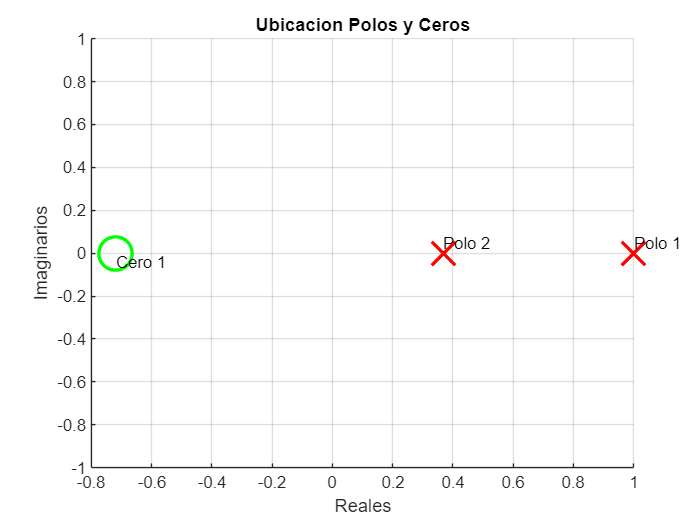

hold on;
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); % Polos (x en rojo)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); % Ceros (o en verde)

grid on;

for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end

xlabel('Reales');
ylabel('Imaginarios');

title('Ubicacion Polos y Ceros');

### Paso 3 - Determinar asintotas

Para determinar asintotas es igual que en una funcion de transferencia en S, teniendo esto en cuenta, La cantidad de polos y ceros sirven para calcular la cantidad de ramificaciones que tiene el sistema entonces para ello tenemos en cuenta que $n=\textrm{polos}$ y $m=\textrm{ceros}$, la cantidad de ramificaciones del sistema es la diferencia que hay entre la cantidad de polos y ceros del sistema

Entonces: 

Si tenemos dos polos ($1\;y\;0\ldotp 3679\;$) y un cero ($-0\ldotp 7195$) entonces $n=2$ y $m=1$ teniendo en cuenta:

La cantidad de ramificaciones es $n-m=\textrm{ramificaciones}\;\textrm{del}\;\textrm{sistema}$ por lo que remplazando nos da que$2-1=1\;$Entocnes el sistema solo tiene una ramificacion.

Ahora con esto podemos hallar las asintotas del sistema, su formula es:

$\frac{180\left(2N+1\right)}{n-m}$ donde N es la cantidad de ramificaciones por lo que simplemente es ir aumentando su valor hasta el maximo de ramificaciones del sistema, como en este caso solo tenemos 1 ramificacion partimos que N=0 y luego N=1.

N =1;
Valores_asintotas = (180 * (2 * N + 1)) / 2

Valores_asintotas = 270

fprintf('polos del sistema\n');

polos del sistema


n_polos = length(polos)

n_polos = 2

fprintf('Ceros del sistema\n');

Ceros del sistema


n_ceros = length(ceros)

n_ceros = 1

n_asintotas = n_polos - n_ceros

n_asintotas = 1


% Graficar el Lugar Geométrico de las Raíces (LGR)
fprintf('*** Graficar el Lugar Geométrico de las Raíces (LGR) ***\n');

*** Graficar el Lugar Geométrico de las Raíces (LGR) ***


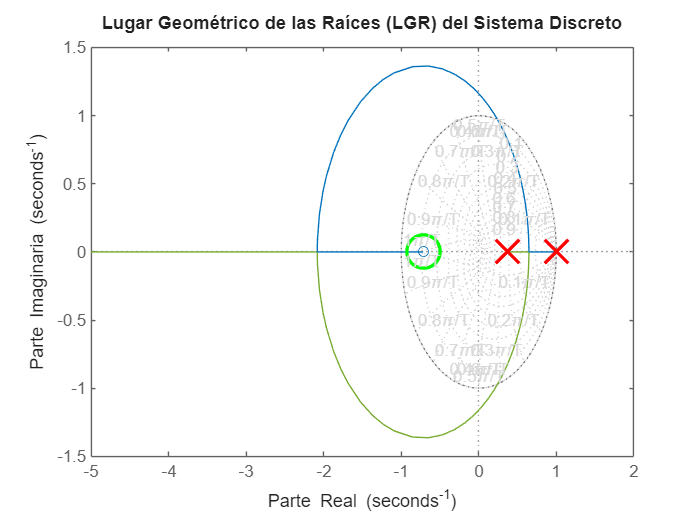

figure;
rlocus(sistema);
title('Lugar Geométrico de las Raíces (LGR) del Sistema Discreto');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

hold on;
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); % Polos (x en rojo)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); % Ceros (o en verde)

for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end

### Paso 4 - Interseccion de las asintotas

Seguido hallaremos el centroide, este es el punto donde se interseccionan las asintotas y queda exactamente sobre el eje real. El centroide no es una raiz del sistema si no es solo un punto que nos muestra como se distribuyen las ramas de LGR que se dirigen hasta el infinito para ello tenemos una formula donde es la sumatoria de los polores solo la parte real y lo ceros tambien su parte real si lo corresponde.


$$\textrm{Centroide}=\frac{\Sigma n-\Sigma m}{n-m}$$


polos = pole(sistema)

polos =     1.0000
    0.3679


ceros = zero(sistema)

ceros = -0.7181


$$\textrm{Centroide}=\frac{\left(1+0\ldotp 3679\right)-\left(-0\ldotp 7195\right)}{1}\;\to \frac{1\ldotp 3679+0\ldotp 7195}{1}\to \frac{2\ldotp 0874}{1}=2\ldotp 0874$$


fprintf('polos del sistema\n');

polos del sistema


n_polos = length(polos);
fprintf('Ceros del sistema\n');

Ceros del sistema


n_ceros = length(ceros);
n_asintotas

n_asintotas = 1


% Graficar el Lugar Geométrico de las Raíces (LGR)
fprintf('*** Graficar el Lugar Geométrico de las Raíces (LGR) ***\n');

*** Graficar el Lugar Geométrico de las Raíces (LGR) ***


figure;
rlocus(sistema);
title('Lugar Geométrico de las Raíces (LGR) del Sistema Discreto');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

sum_pyc= (sum(real(polos)) - sum(real(ceros)))

sum_pyc = 2.0860

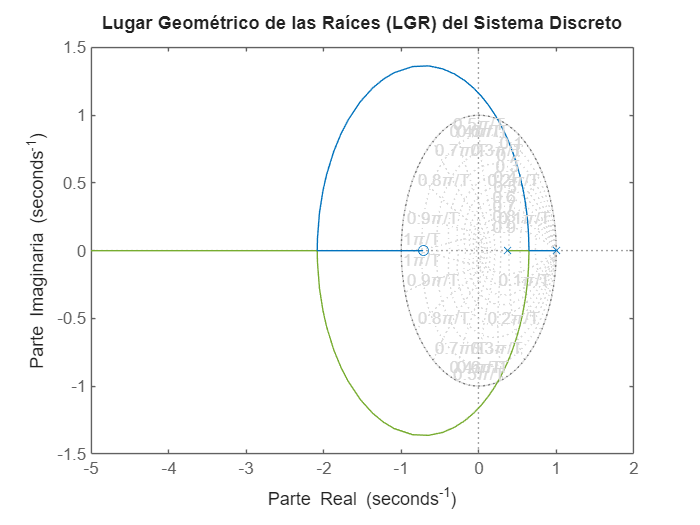

centroide =  sum_pyc / (n_polos - n_ceros); % Centroide en el eje real


for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)
    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end

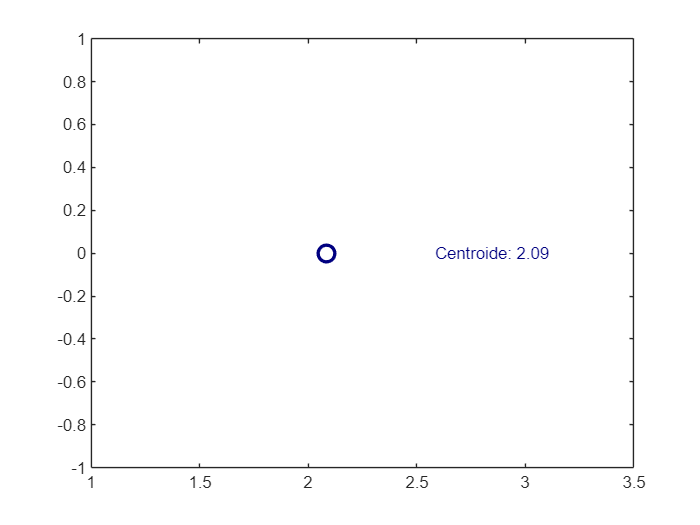

plot(centroide, 0, 'o', 'MarkerSize', 10, 'LineWidth', 2, 'Color', [0, 0, 0.5]); % Centroide en azul oscuro
text(centroide + 0.5, 0, sprintf('Centroide: %.2f', centroide), 'FontSize', 10, 'Color', [0, 0, 0.5]); % Texto

### Paso 5 - Puntos de ruptura

Continuamos con los puntos de ruptura donde se separan las asintotas. Los puntos de ruptura son aquellos puntos en los cuales las ramas del lugar de las raíces se separan o se juntan, o puntos en los cuales las ramas del lugar de las raíces cambian de dirección debido a un cambio en el parámetro del sistema (por ejemplo, un cambio en la ganancia). Estos puntos pueden ser críticos cuando se analizan las asintotas del lugar de las raíces, que son las direcciones a las cuales las ramas del lugar de las raíces tienden cuando se alejan del origen del plano complejo.


$$K\frac{A\left(Z\right)}{B\left(Z\right)}$$


Polinomio=[ -2, 1.3679];
disp('puntos de ruptura:');

puntos de ruptura:


disp(roots(Polinomio));

    0.6839




$$K\frac{A\left(Z\right)}{B\left(Z\right)}$$


Se factoriza, luego se deriva con signo negativo:


$$K\frac{\left(0\ldotp 3679z+0\ldotp 2642\right)}{\left(z-0\ldotp 3679\right)\left(z-1\right)}$$



$$K\frac{\left(z-0\ldotp 3679\right)\left(z-1\right)}{0,3679z+0\ldotp 2642}$$


$K\frac{d}{\textrm{dz}}$-$\left(z^2 \;\;-\;z\;-0\ldotp 3679z+0\ldotp 3679\right)$

= $\frac{d}{\textrm{dz}}$-$\left(z^2 \;\;-1\ldotp 3679z+0\ldotp 3679\right)$

= -2z + 1,3679 + 0 = 0

puntos de ruptura z = $\frac{-1\ldotp 3679}{-2}$

= 0.684 

### Paso 6 - Criterio de Jury

Para hallar los valores donde K es estable podemos usar este metodo que nos permite saber en que momentos la ganancia hace que el sistema sea estable. Para eso usaremos esta formula 

$z^2 +z\left(-1\ldotp 3679+0\ldotp 3679k\right)+\left(0\ldotp 3679+0\ldotp 2642k\right)=0$  *Ecuacion caracteristica del sistema*

Teniendo esta formula el criterio de Jury no sdice que debemos hacer una desigualdad usando el suiguiente criterio.


$$\left|a_n \right|<a_0$$


Donde  $G\left(z\right)=a_0 +a_1 +a_2 \ldotp \ldotp \ldotp a_n$


$$z^2 +z\left(-1\ldotp 3679+0\ldotp 3679k\right)+\left(0\ldotp 3679+0\ldotp 2642k\right)=0$$


$a_0 =1$ unicamente usamos el coeficiente que acompaña z


$$a_1 =-1\ldotp 3679+0\ldotp 3679k$$


Ahora resolveremos la desigualdad para saber cuales son los valores donde K hace el sistema estable

$\left|-1\ldotp 3679+0\ldotp 3679k\right|<1$ Reolviendo esta inecuacion nos da que $k>1$

Gracias a una propiedad de las inecuaciones con valor absoluto podemos obtener la siguiente expresion 


$$-1<\left|-1\ldotp 3679+0\ldotp 3679k\right|<1$$
 

Como ya resolvimos la derecha procederemos a resolver la izquierda, osea:

$-1<\left|-1\ldotp 3679+0\ldotp 3679k\right|$  Resolviendo nos da que  $k<6\ldotp 43$

La primera parte nos da que 


$$1<k<6\ldotp 43$$
 

estos valores nos da una aproximacion de lo que se refiere la estabilidad por lo que peude que entre estos valores nos de la estabilidad necesaria del sistema pero aun nos falta comprar $a_0 \;$con $a_2$

Donde $a_2 =0\ldotp 3679+0\ldotp 2642k$

Procedemos hacer lo mismo que hicimos anteriormente:


$$\left|0\ldotp 3679+0\ldotp 2642k\right|<1$$


Aplicando la misma propiedad del valor absoluto en las desigualdades:


$$-1<\left|0\ldotp 3679+0\ldotp 2642k\right|<1$$


Procediendo a resolver las dos partes de la desigualdad

$-1<\left|0\ldotp 3679+0\ldotp 2642k\right|$                                    y                                    $\left|0\ldotp 3679+0\ldotp 2642k\right|<1$

Resolviendo 


$$-1<\left|0\ldotp 3679+0\ldotp 2642k\right|\to k>-5\ldotp 18$$


 Y


$$\left|0\ldotp 3679+0\ldotp 2642k\right|<1\to k>2\ldotp 39$$


Ahora hacemos la interseccion de estos puntos hasta encontrar valores que satisfagan las dos desigualdades osea 


$$1<k<2\ldotp 39$$
 

Este rango de valores hacen que el sistema se haga estable.

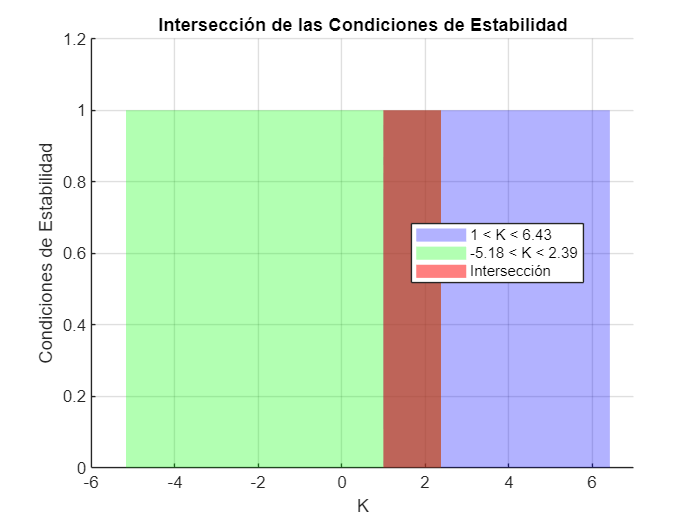

% Valores límites de las desigualdades
K1_min = 1;
K1_max = 6.43;
K2_min = -5.18;
K2_max = 2.39;

% Crear un rango de valores para K
K = linspace(-6, 7, 1000); % Ajusta el rango para cubrir los límites

% Condiciones de las desigualdades
cond1 = (K > K1_min) & (K < K1_max); % 1 < K < 6.43
cond2 = (K > K2_min) & (K < K2_max); % -5.18 < K < 2.39


interseccion = cond1 & cond2;

% Graficar
figure;
hold on;
fill([K(K < K1_max & K > K1_min), fliplr(K(K < K1_max & K > K1_min))], ...
     [ones(1, sum(K < K1_max & K > K1_min)), zeros(1, sum(K < K1_max & K > K1_min))], ...
     'blue', 'FaceAlpha', 0.3, 'EdgeColor', 'none'); % Región de la primera condición

fill([K(K < K2_max & K > K2_min), fliplr(K(K < K2_max & K > K2_min))], ...
     [ones(1, sum(K < K2_max & K > K2_min)), zeros(1, sum(K < K2_max & K > K2_min))], ...
     'green', 'FaceAlpha', 0.3, 'EdgeColor', 'none'); % Región de la segunda condición

fill([K(interseccion), fliplr(K(interseccion))], ...
     [ones(1, sum(interseccion)), zeros(1, sum(interseccion))], ...
     'red', 'FaceAlpha', 0.5, 'EdgeColor', 'none');


xlabel('K');
ylabel('Condiciones de Estabilidad');
legend({'1 < K < 6.43', '-5.18 < K < 2.39', 'Intersección'}, 'Location', 'best');
title('Intersección de las Condiciones de Estabilidad');
grid on;
xlim([-6 7]);
ylim([0 1.2]);
hold off;

### RESPUESTA DEL SISTEMA 

K =0.8% Valores estables deben ser entre 1 y 2.39 para que el sistema sea estable

K = 0.8000


Ts = 0.1; % Tiempo de muestreo en segundos (ajústalo según tu sistema)
% Numerador: K(s+3)
numerador = [0.3679*K 0.2646*K];

% Denominador: (s + 5)(s + 6)(s^2 + 2s + 2)(s + 3)
denominador = conv([1, -0.3679], [1, -1]);  % (s + 5)(s + 6)


fprintf('*** Funcion de transferencia  ***\n');

*** Funcion de transferencia  ***


sys = tf(numerador, denominador,Ts)/(1+tf(numerador, denominador,Ts)) %Aqui se hace la suma G(z) / 1 + G(z) para poder obtener la respuesta del sistema al escalon unitario


sys =
 
   0.2943 z^3 - 0.1909 z^2 - 0.1813 z + 0.07788
  ----------------------------------------------
  z^4 - 2.441 z^3 + 2.416 z^2 - 1.188 z + 0.2132
 
Sample time: 0.1 seconds
Discrete-time transfer function.
Model Properties


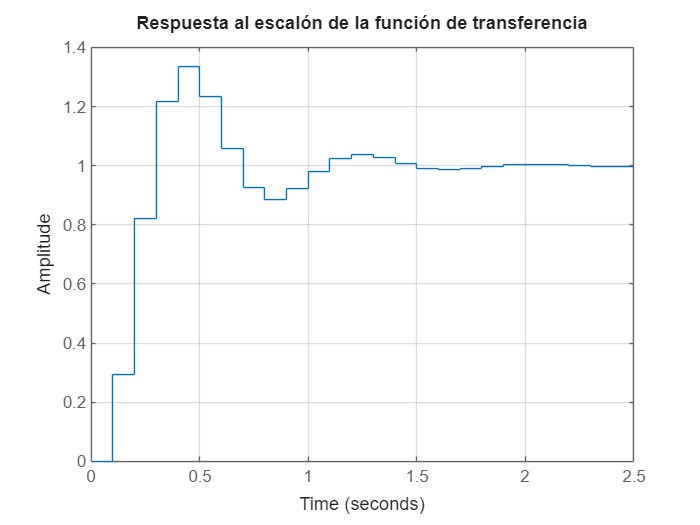


% Respuesta al escalón
figure;
step(sys);
title('Respuesta al escalón de la función de transferencia');
grid on;